## Import Data

### Column headings were added manually using a text editor. Original dataset can be found at: https://archive.ics.uci.edu/dataset/45/heart+disease

data = importdata('heart+disease\processed.cleveland.data')

data = struct with fields:
          data: [88×14 double]
      textdata: {'age'  'sex'  'cp'  'trestbps'  'chol'  'fbs'  'restecg'  'thalach'  'exang'  'oldpeak'  'slope'  'ca'  'thal'  'num'}
    colheaders: {'age'  'sex'  'cp'  'trestbps'  'chol'  'fbs'  'restecg'  'thalach'  'exang'  'oldpeak'  'slope'  'ca'  'thal'  'num'}


Convert struct to table for easier handling and visualisation

data = array2table(data.data, 'VariableNames', data.colheaders);

## Visualise Dataset

whos data

  Name       Size            Bytes  Class    Attributes

  data      88x14            13661  table              



### Get first few rows of the dataset.

head(data)

    age    sex    cp    trestbps    chol    fbs    restecg    thalach    exang    oldpeak    slope    ca    thal    num
    ___    ___    __    ________    ____    ___    _______    _______    _____    _______    _____    __    ____    ___

    63      1     1       145       233      1        2         150        0        2.3        3      0      6       0 
    67      1     4       160       286      0        2         108        1        1.5        2      3      3       2 
    67      1     4       120       229    

## Preprocessing Data

### Eliminate NaN values in the dataset by replacing with average 

% Loop through each column
for i = 1:width(data)
    if isnumeric(data{:, i}) % Check if column is numeric
        colMean = mean(data{:, i}, 'omitnan'); % Compute column mean, ignoring NaN
        data{isnan(data{:, i}), i} = colMean; % Replace NaN with mean
    end
end
sum(ismissing(data)) 

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0


### Extract Features and Target

X = data(:, 1:13);      % extract features
y = data(:, 14);        % extract target
X = table2array(X);
y = table2array(y);     % 0: absent, 4: present

     0
     2
     1
     0
     0
     0
     3
     0



## Training the Neural Network

net = patternnet(3)     % 3 neurons in hidden layer

net =

    Neural Network
 
              name: 'Pattern Recognition Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 3
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      inp

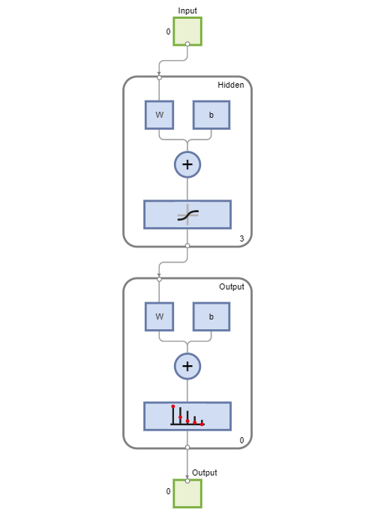

view(net)

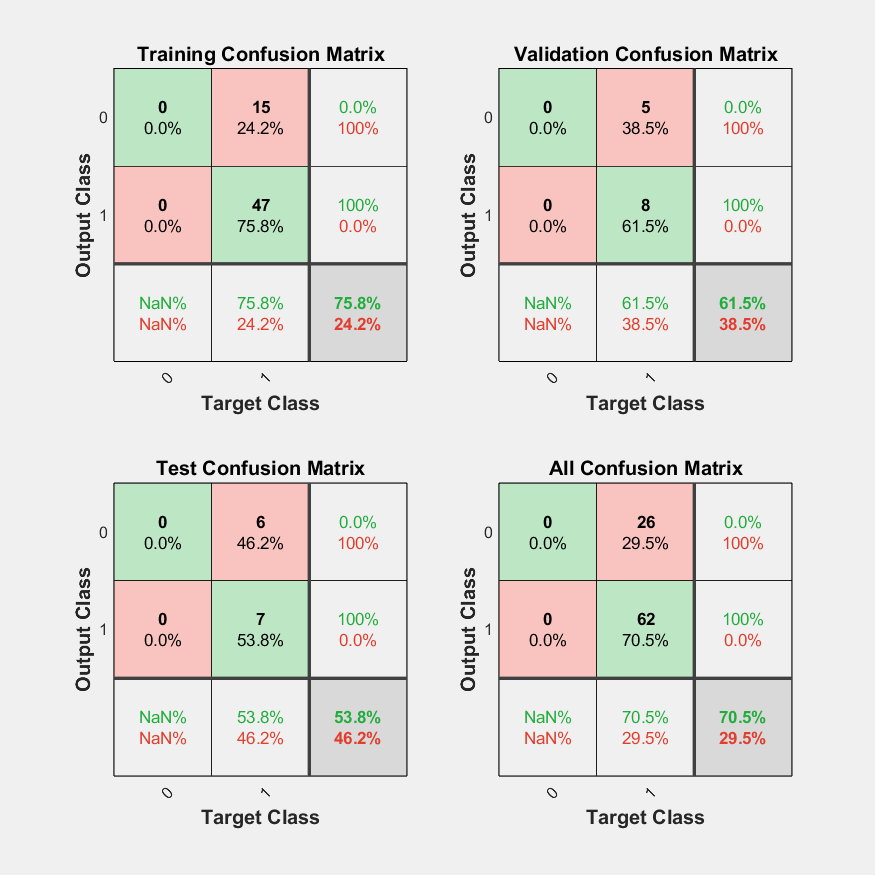

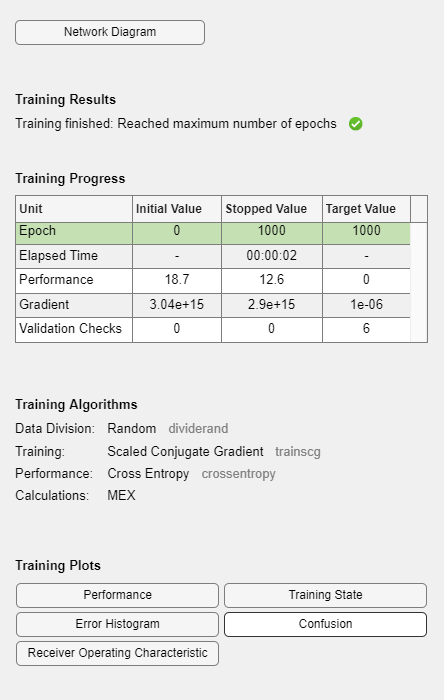

[net, tr] = train(net, X', y');